# **Relatório do Laboratório de Sinais e Sistemas**

**Q1.1**

samplerateQ1 = 16e3; % Hz
t = (0:1/samplerateQ1:2); % s
f1 = 32; % Hz
f2 = 40; % Hz
x = cos(2*pi*f1*t) + cos(2*pi*f2*t);
figure('Units', 'pixels', 'Position', [0, 0, 1000, 500]); 
plot(t,x)

%[xi, yi] = ginput;
%period = mean(diff(xi))

Teoricamente, o período fundamental do sinal é o mínimo múltiplo comum (MMC) dos períodos fundamentais de cada cosseno.

Ao trabalhar com números racionais (como os períodos fundamentais de cada cosseno, que são o inverso das suas frequências), temos:


$$\text{MMC} = \frac{\text{MMC dos numeradores (= 1)}}{\text{MDC dos denominadores}}$$


function mmc = LCM(a,b)
    [num_a, den_a] = rat(a);
    [num_b, den_b] = rat(b);
    mmc = (lcm(num_a, num_b))/(gcd(den_a, den_b));
end
theoretical_period = LCM(1/f1, 1/f2)

theoretical_period = 0.1250

O período que medimos, como a média das diferenças subsequentes entre "localizações periódicas" no sinal, vai de acordo com o período teórico que calculámos acima.

% "Localizações Periódicas" é muito mau ahhahah tenho de mudar

**Q1.2**

period_in_samples = LCM(theoretical_period, 1/samplerateQ1) * samplerateQ1

period_in_samples = 2000

Direct measurement:

plot(x)

%meter foto com os pontos

Com downsample:

y = downsample(x,3);
period_in_samples_y = LCM(theoretical_period, 1/(samplerateQ1/3))*samplerateQ1/3

period_in_samples_y = 2000

Why does this only seemingly disagree with direct measurement from `plot(y)`?

plot(y);
%[xxx,yyy] = ginput;
%measured_period_samples_y = diff(xxx)
% Cenas a mencionar:
% 1) fator pelo qual diminuimos sampling rate = fator pelo qual aumentamos
% período, no tempo MAS como # de samples/tempo também diminui pelo mesmo
% fator,  (T' = 3T MAS n'/T' = (1/3) *n/T
% 2) cena sobre o ponto não apanhar ali mm o pico
% meter foto com os pontos

Teoricamente diferem por causa do domínio, o medido terá que ser um inteiro

**Q1.3**

A4 = 440; % Hz
function frequency = noteFrequencyFromHalfsteps(no_halfsteps)
    A4 = 440; % Hz
    ratio = 2^(1/12);    
    frequency = A4 * ratio^no_halfsteps;
end

C4 = noteFrequencyFromHalfsteps(-9);
E4 = noteFrequencyFromHalfsteps(-5);
Fs4 = noteFrequencyFromHalfsteps(-3);
G4 = noteFrequencyFromHalfsteps(-2);
B4 = noteFrequencyFromHalfsteps(2);
F4 = noteFrequencyFromHalfsteps(-4);

Use the `seqsin` function to generate a sequence of sinusoids and silence gaps. Create x as the following sequence and listen to the resulting signal:


$$\text{R(0.7), E4(0.25), E4(0.25), F4(0.25), F\#4(0.5), A4(0.25),} \\

\text{F\#4(0.25), A4(0.25), F\#4(0.25), F\#4(0.25), F4(0.25),} \\

\text{E4(0.25), B4(0.25), E4(0.25), E4(0.5), R(0.7)}$$


noteSeq = seqsin(samplerateQ1, 0, 0.7, E4, 0.25, E4, 0.25, F4, 0.25, Fs4, 0.5, A4, 0.25, ...
            Fs4, 0.25, A4, 0.25, Fs4, 0.25, Fs4, 0.25, F4, 0.25, ...
            E4, 0.25, B4, 0.25, E4, 0.25, E4, 0.5, 0, 0.7);
soundsc(noteSeq, samplerateQ1)

**Q1.4**

samplerate=16e3

samplerate = 16000

u = @(t) (t >= 0);
t = (-2:1/samplerate:2);

O valor do degrau unitário muda em t=0, assim, para u(at+b) obtêm-se o valor para a mudança de t=-b/a.

se a<0 u(at+b) = u(-t-t0), 

se a>0 u(at+b) = u(t-to)

a=rand

a = 0.6787

b=rand

b = 0.7577

t0=-b/abs(a)

t0 = -1.1164

sinal_a = sign(a)

sinal_a = 1

plot(t,u(a*t+b),'b--', 'LineWidth', 2); hold on
plot(t, u(sinal_a*t-t0),"g"); hold off
% relatório por varios lado a lado

s = @(t) (t >= 0).*t;                   % Unit ramp
uD = @(t,D) (1/D)*(s(t+D/2)-s(t-D/2));  % Approximate unit step
duD = @(t,D,h) (uD(t+h/2,D)-uD(t-h/2,D))/h; % Numeric derivative
deltaD = @(t,D) duD(t,D,1e-6);          % Approximate unit impulse 

O sinal tem valores diferentes de zero entre t0-D/2 e t0+D/2:

D = rand

D = 0.7431

T = D/2 

T = 0.3716

t00 = rand

t00 = 0.3922

%dt para aumentar a resolução, aka + data points do que o default 1 em 1
dt=D/1000

dt = 7.4313e-04

t2 = t00-T-D*1000:dt:t00+T+D*1000

t2 =  -743.1118 -743.1111 -743.1103 -743.1096 -743.1088 -743.1081 -743.1073 -743.1066 -743.1059 -743.1051 -743.1044 -743.1036 -743.1029 -743.1021 -743.1014 -743.1007 -743.0999 -743.0992 -743.0984 -743.0977 -743.0969 -743.0962 -743.0955 -743.0947 -743.0940 -743.0932 -743.0925 -743.0917 -743.0910 -743.0903 -743.0895 -743.0888 -743.0880 -743.0873 -743.0865 -743.0858 -743.0851 -743.0843 -743.0836 -743.0828 -743.0821 -743.0813 -743.0806 -743.0799 -743.0791 -743.0784 -743.0776 -743.0769 -743.0761 -743.0754


plot(t2, deltaD(t2-t00,D)); hold off
% meter -0.5 a 1.5 no yy

a = 0.5
t3 = (-5:0.001:5)
deltaA = deltaD(t3, D)/abs(a);
plot(t3, deltaA, "b--", "LineWidth",2); hold on
plot(t3, deltaD(a*t3, D), "r"); hold on

**Q2.1**

system1 = @(x) filter([1 zeros(1,round(0.4*samplerateQ1) - 1) 0.7],1,x);
[x,samplerateQ2] = audioread('echoin.wav');

soundsc([x; system1(x)], samplerateQ2); 

% Em vez de só ouvir o sinal transformado, ouvimos o sinal de entrada 
% antes do sinal de saída - [entrada; saída] -, para poder comparar os dois.

Ao ouvir o resultado da aplicação do sinal lido do ficheiro `echoin.wav` ao sistema `system1`, conseguimos isolar o sinal original, no entanto, ouvimo-lo repetido pouco depois, como que um eco, menos intenso.

Perante o sistema definido, isto faz todo o sentido. Analisemos porquê.

O sistema sobrepõe 2 sinais: o sinal de entrada e uma transformação do sinal de entrada pesado por uma constante. Nesta última parcela, ao usar uma constante $<1$, o sinal é atenuado e, com uma transformação na variável independente, é ainda atrasado. Estes dois fenómenos faz com que, ao sinal de entrada, estejamos a somar algo que simule o seu eco.

**Q2.2**

A figura parece representar uma sobreposição de inúmeros impulsos com diferentes atrasos, que diminuem progressivamente  ($\sum\limits_i a_i \cdot\delta(t-t_{0_i})$), com $a_{i+1}$ aproximadamente menor que $a_i$). 

Por isto, observamos menos impulsos mais fortes para atrasos pequenos, e mais impulsos mais fracos para atrasos maiores.

Este padrão ocorre devido ao comportamento físico do sinal numa sala como a descrita. Ao ser emitido pela fonte, o sinal reflete-se nas paredes, onde é parcialmente absorvido e atenuado a cada reflexão. Assim, o sinal muda de direção e perde intensidade ao longo do tempo. Quanto mais reflexões o sinal sofre, maior distância percorre e, consequentemente, maior é o atraso antes de atingir o recetor.

Inicialmente, para atrasos pequenos, há menos impulsos porque o sinal segue caminhos diretos e curtos até ao recetor. Estes caminhos envolvem menos reflexões, resultando em menor atenuação. Com o passar do tempo, as frentes de onda que seguiram caminhos mais indiretos, sofrendo múltiplas reflexões, começam a chegar ao recetor. Estes sinais percorreram distâncias maiores e foram mais atenuados, o que resulta em impulsos mais fracos com atrasos maiores. São mais impulsos pois há muitas direções diferente das "ótimas", que levam aos caminhos mais curtos.

Assim, a resposta ao impulso reflete a distribuição das trajetórias que o sinal percorre.

**Q2.3**

% posição 3d do receiver
mic = [1 2 1];
n = 12;
load fingerprint.mat

%dimensões da sala
rm_now = [20 15 10];
%refletividade das paredes de madeira
r_wood = 0.6;
%refletividade das paredes de betão
r_concrete = 0.9;
%hipóteses de distâncias da fonte ao recetor
distance3 = 3;
distance20 = 20;

%fonte localizada a 1m de altura, distância horizontal desconhecida.
%Coordenadas, supondo que a posição no y é a mesma e no x é a 3m/ 20m de
%distância da fonte:
src_3 = [mic(1)+distance3, mic(2), 1];
src_20 = [mic(1)+distance20, mic(2), 1];

%paredes de madeira com o recetor a 3m de distância
h_wood_3 = rir(samplerate, mic, n, r_wood, rm_now, src_3);
%paredes de madeira com o recetor a 20m de distância
h_wood_20 = rir(samplerate, mic, n, r_wood, rm_now, src_20);
%paredes de betão com o recetor a 3m de distância
h_concrete_3 = rir(samplerate, mic, n, r_concrete, rm_now, src_3);
%paredes de betão com o recetor a 20m de distância
h_concrete_20 = rir(samplerate, mic, n, r_concrete, rm_now, src_20);

%saída/ convolução de cada hipótese 
y_wood_3 = conv(x, h_wood_3);
y_wood_20 = conv(x, h_wood_20);
y_concrete_3 = conv(x, h_concrete_3);
y_concrete_20 = conv(x, h_concrete_20);

%som original
%soundsc(y, samplerate);
%pausa para não sobrepor os sons
%pause(7);

%sons produzidos nas diferentes hipóteses:
%soundsc(y_wood_3, samplerate); 
%pause(7);
%soundsc(y_wood_20, samplerate);    
%pause(7);
%soundsc(y_concrete_3, samplerate);  
%pause(7);
%soundsc(y_concrete_20, samplerate); 

Ao ouvir os sons conclui-se que as paredes de concreto levam a um maior eco o que é esperado tendo em conta  o seu maior índice de refletividade. Uma maior distância leva a um *delay* maior na receção do som inicial. Desta forma, conclui-se que o mais provável é que a fonte esteja localizada a uma distância de 3 metros do recetor e as paredes da sala serão de betão (*concrete*).

Visto que esta é uma análise subjetiva, sujeita a erros, optamos por vizualisar o plot produzido através de cada uma das hipóteses de modo a confirmar as observações retiradas da audição dos diferentes sons.

MAYBE MADEIRA A 20M NOT SUREEEE

ty = (0:length(y)-1)/samplerate;
tyw3 = (0:length(y_wood_3)-1)/samplerate;
tyw20 = (0:length(y_wood_20)-1)/samplerate;
tyc3 = (0:length(y_concrete_3)-1)/samplerate;
tyc20 = (0:length(y_concrete_20)-1)/samplerate;
figure;
plot(ty, y,'b', 'LineWidth', 1.5); hold on
plot(tyw3, y_wood_3, 'c', 'LineWidth', 1.5); hold off
title("original vs paredes de madeira a 3m");
legend('original', 'wood 3');
plot(ty, y,'b', 'LineWidth', 1.5); hold on
plot(tyw20, y_wood_20,'c', 'LineWidth', 1.5); hold off
title("original vs paredes de madeira a 20m");
legend('original', 'wood 20');
plot(ty, y,'b', 'LineWidth', 1.5); hold on
plot(tyc3, y_concrete_3, 'c', 'LineWidth', 1.5); hold off
title("original vs paredes de betão a 3m");
legend('original', 'concrete 3');
plot(tyc20, y_concrete_20, 'c', 'LineWidth', 1.5); hold on
plot(ty, y,'b', 'LineWidth', 1.5); hold off
title("original vs paredes de betão a 20m");
legend('concrete 20', 'original');

**Q2.4**

system1 = @(x) filter([1 zeros(1,round(0.4*samplerate) - 1) 0.7],1,x);
samplerate = 16e3;
t = (-4:1/samplerate:4);
%valor fornecido pela docente
omega = 27;
x1 = cos(omega*t);
y1 = system1(x1);

% Parametros do sistema 1
deslocamento = 0.4; 
escalamento = 0.7;

% Amplitude e fases teóricos para Acos(omega*t+phi). Demonstração abaixo
A = sqrt(1 + escalamento^2 + 2 * escalamento * cos(-omega * deslocamento)); 
phi = atan2(escalamento * sin(-omega * deslocamento), 1 + escalamento * cos(omega * deslocamento));

y1_teorico = A * cos(omega * t + phi);
%plot do sinal obtido pelo sistema1
plot(t, y1, 'r', 'LineWidth', 1.5); hold on;
%plot do sinal previsto (Acos(omega*t+phi))
plot(t, y1_teorico, 'k--', 'LineWidth', 1); hold off;
title('Resposta ao sistema 1: y1(t) vs Sinal previsto (teórico)');
xlabel('Tempo (s)');
ylabel('Amplitude');
legend('Output do sistema: y1(t)', 'Sinusoide previsto');
grid on;

**Q2.5**

## Linearidade

function test_linearity(t, x1,x2, a)
    s2_x1x2 = system2(a*(x1+x2),t);
    s2_x1_s2_x2 = a*system2(x1,t) + a*system2(x2,t);
    
    disp("S2(a(x1+x2)) (blue) vs a*S2(x1)+a*S2(x2) (green)")
    plot(t, s2_x1x2); hold on;
    plot(t, s2_x1_s2_x2, "g--"); hold off
end

t = -10:10;
x1 = deltaD(t-1,1);
x2 = -3*deltaD(t-2,1);
a=17;

test_linearity(t, x1, x2, a)

x1 = uD(t-4, 1);
x2 = -uD(t+1, 1);
a = 3

test_linearity(t, x1, x2, a)
t=-40:40
x1 = cos(t) + sin(t);
x2 = cos(t-1) + sin(t-5);
a = 20;
test_linearity(t, x1, x2, a)

Ao testar sinais fundamentais na construção de outros sinais, mas todos diferentes - um impulso, um degrau unitário e um $cos$, observámos sempre um comportamento linear. 

Computacionalmente, não nos é possível testar o espaço todo de sinais de entrada - já que este é infinito. No entanto, uma vez que os sinais que nós testámos poderiam ser usados para construir qualquer sinal de entrada neste espaço de sinais, através de deslocamentos no tempo e combinações lineares, estamos bastante confiantes de que se trata de um sistema linear.

Há que reforçar que não podemos constatar com certeza a linearidade, só podemos comentar os exemplos que observámos. (Exemplo: se, para t=1000, o sistema não for linear, tal não estaria incluído nos nossos testes. Como não temos modo de criar uma suite de testes absolutamente exaustiva, não podemos generalizar a nossa conclusão.)

## Invâriancia no Tempo

function test_timeInvariance(t, t0, x)
    x_t = x(t);
    x_t_t0 = x(t-t0);
    y_t_t0 = system2(x_t, t);
    S2_x_t_t0 = system2(x_t_t0, t);

    font_s = 16;

    plot(t, S2_x_t_t0, "r"); hold on; plot(t+t0, y_t_t0, "b--"); hold off; 
    xlim([-10 10]); ylim([-0.2 1.2]);
    xlabel('t', 'FontSize', font_s, 'Interpreter', 'latex');
    ylabel('$S(x(t))$', 'FontSize', font_s, 'Interpreter', 'latex');
    title('\fontsize{16} {\color{red}S(x(t-t0)) \color{black} vs \color{blue}y(t-t0)}')
end

t = -10:10;
x1 = @(t) deltaD(t-1,1);

test_timeInvariance(t, 2, x1)
test_timeInvariance(t, 3, x1)

Com um exemplo, vemos que o sinal não é invariante no tempo.

Nestes gráficos, vemos a sobreposição de 2 casos.

Em vermelho, vemos o resultado da aplicação do `system2` num sinal `x` que foi deslocado no tempo. Em azul, vemos o resultado, deslocado no tempo, da aplicação do `system2 num sinal x`.

No primeiro gráfico, o deslocamento no tempo é de 2 unidades, ao passo que, no segundo, é de 3. Como podemos ver, no segundo gráfico os sinais obtidos não são equivalentes, o que nos diz que o sistema não pode ser invariante no tempo - se pudesse, os sinais seriam iguais independentemente do deslocamento temporal.

## Memória e Causalidade

function test_memory_or_causality(t, x1, x2, t0)
    % Let x1 and x2 be 2 similar signals which we will evaluate at point t0.
    % In constructing them, we should make them essentially the same, but
    % different only at some point t1≠t0.
    % If the output signal at t0 changes, then the system has memory.

    S2_x1 = system2(x1, t);
    S2_x2 = system2(x2, t);
    
    font_s = 16;

    figure;
    plot(t, x1, "r"); hold on; plot(t, x2, "g--"); xline(t0, 'k--', 'LineWidth', 1.5); hold off;
    xlim([-10 10]); ylim([-1.5 1.5]);
    xlabel('t','FontSize',font_s, 'Interpreter','latex'); ylabel('$x(t)$', 'FontSize',font_s, 'Interpreter','latex');
    title("Input signals: $\texttt{x1}$ in red, $\texttt{x2}$ in green", 'Interpreter','latex', 'FontSize', font_s);    
    

    figure;
    plot(t, S2_x1, "r"); hold on; plot(t, S2_x2, "g--"); xline(t0, 'k--', 'LineWidth', 1.5); hold off;
    xlim([-10 10]); ylim([-1.5 1.5]);
    xlabel('t','FontSize',font_s, 'Interpreter','latex'); ylabel('$S(x(t))$', 'FontSize',font_s, 'Interpreter','latex');
    title("Output signals: $S(\texttt{x1})$ in red, $S(\texttt{x2})$ in green", 'Interpreter','latex', 'FontSize', font_s);    

end


x1 = deltaD(t-4,1) + deltaD(t-3,1) - deltaD(t+4,1);
x2 = deltaD(t-3,1) - deltaD(t+4,1);
t0 = -4;

test_memory_or_causality(t, x1, x2, t0)

Por contra-exemplo, demonstramos que o sistema tem memória, e que não é causal: ao alterarmos o sinal de entrada num ponto t1=4 diferente do ponto t0=-4, e inclusive após deste, a saída do sistema altera-se nesse ponto t0=4, ou seja, a saída num ponto no tempo depende da entrada noutro ponto no tempo - cumprindo a definição de memória de um sistema -, ponto este que é posterior no tempo ao inicial - violando a definição de causalidade de um sistema.

## Estabilidade

## Invertibilidade

plot(t, system2(system2(x1, t), t), "g-"); hold on; plot(t, x1, "r--"); hold off;

**Q3.1**

t = (-320:320)'/samplerate;
w0 = 2*pi*100;
T = 2*pi/w0;
ak = @(k) sin(k*w0*T/4)./(k*pi).*exp(-1i*k*w0*T/4);
a0 = 1/2; % Segregate a0, which often has a different expression
N = 100; % Order of the Fourier expansion
xN = exp(1i*w0*t*(-N:N))*[ak(-N:-1) a0 ak(1:N)].';
plot(t,real(xN)); grid

Os detalhes da forma do sinal demonstram que a SFC é convergente pois verifica-se que é absolutamente integrável tem um número finito de máximos e mínimos num período e um número finito de descontinuidades num intervalo de tempo finito 

NÃO SEI SE É BEM ISTO QUE SE OBSERVA??

%spectra: representação do sinal no domínio da frequência
[XN, f] = cftransform(xN, find(t == 0), 1e4, samplerate);
figure;
plot(f, abs(XN)); grid on
title('Spectra');
figure;
plot(f, angle(XN)); grid on
title('Angulo')
figure;
plot(f, real(XN));grid on
title('Re(XN)');
figure;
plot(f, imag(XN));grid on
title('Im(XN)');

**Q3.2 **Analisar os espetro de Q3.1    ERRADO amplitude bue off

D = 1e-6;
f0=w0/(2*pi);
% Par da transformada de fourier de tempo contínuo de sinais periódicos
% (trem de impulsos, como é o caso de ~xN(t)
Xjw= 2*pi*[ak(-N:-1) a0 ak(1:N)]*deltaD(f - ((-N:N)*f0), D).';
figure;
plot(f, abs(Xjw), 'r', 'LineWidth', 1.5); hold on;
plot(f, abs(XN), 'b', 'LineWidth',1.5);
title("theoretical spectra");

**Q4.1**

ADICIONAR NO RELATÓRIO A DEMONSTRAÇÃO

Convolução x(t)*h(t)=y(t)

TFTC --> X(jw)H(jw)=Y(jw)

H(jw)=|H(jw)|e^jangulo

**Q4.2**

samplerate = 16e3;
t = (-10:1/samplerate:10);
omega = [1, 10, 50, 100, 200, 1000];
moduloH = zeros(size(omega));

for i=1:length(omega)
    %sinal sinusoidal
    x=sin(omega(i)*t);
    %resposta do sistema e plot
    y=system3(x,samplerate);
    figure;
    plot(t,y); grid on
    title("resposta do sistema para \omega="+ num2str(omega(i)));

    % para evitar "trasient effects" nas extremidades da variável do tempo
    intervalo_estavel = t>-5 & t<5;
    y_estavel = y(intervalo_estavel);
    % máximo ao mínimo-->2vezes a amplitude
    A = max(y_estavel) - min(y_estavel); 
    moduloH(i) = A / 2 % Convert to amplitude magnitude
end

moduloH =     0.9999         0         0         0         0         0


moduloH =     0.9999    0.9950         0         0         0         0


moduloH =     0.9999    0.9950    0.8939         0         0         0


moduloH =     0.9999    0.9950    0.8939    0.7060         0         0


moduloH =     0.9999    0.9950    0.8939    0.7060    0.4461         0


moduloH =     0.9999    0.9950    0.8939    0.7060    0.4461    0.0992


%plot da variação do módulo de H(jw) com a frequência angular
figure;
plot(omega, moduloH, 'o-');
title('Variação de |H(j\omega)| com \omega');
xlabel('\omega (rad/s)');
ylabel('|H(j\omega)|');
grid on;
%Tipo de filtro:
if moduloH(1) > moduloH(end)
    disp('Filtro passa-baixo');
elseif moduloH(1) < moduloH(end)
    disp('Filtro passa-alto');
else
    disp('Filtro passa-banda');
end

Filtro passa-baixo


Verifica-se assim que se trata de uma filtragem do tipo passa-baixo uma vez que o módulo da resposta em frequência diminui com o aumento da frequência angular. **(explicar que para freqs <wm deixa passar, para maiores atenua a amplitude?)**

**Q4.3**

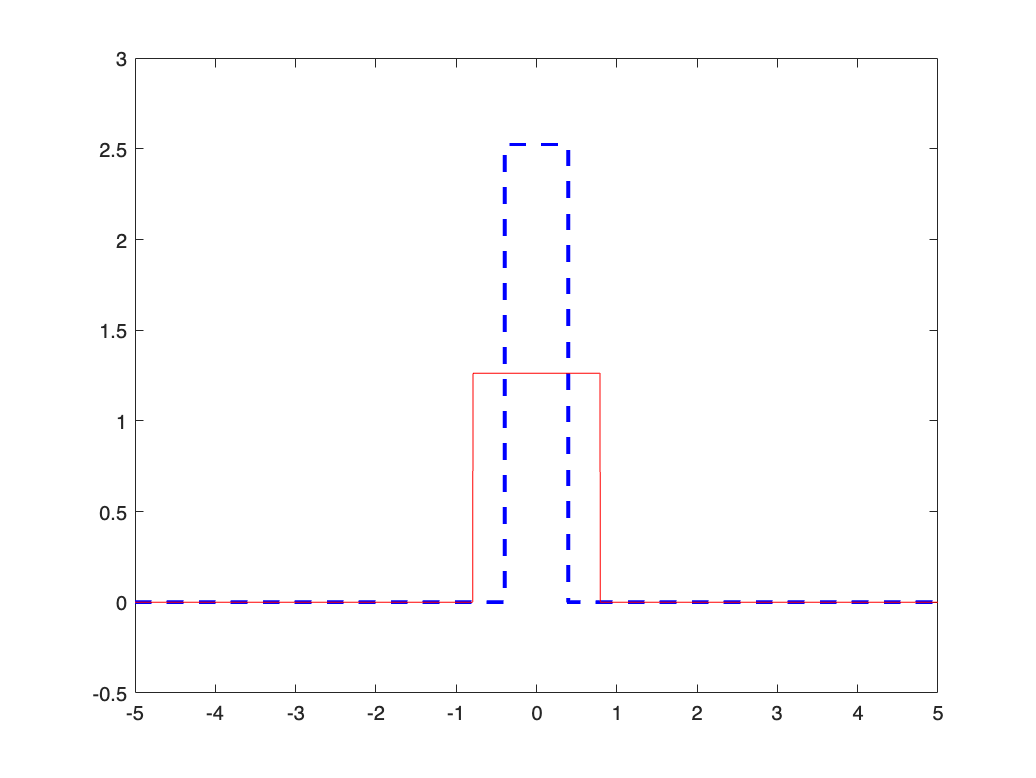

t = (-0.2:1/samplerate:1)';
x = deltaD(t,10/samplerate);
% aproximação da resposta ao impulso (y(t)~h(t))
h = system3(x,samplerate);

Delta_t = 1/samplerate;
% transformada de fourier da resposta ao impulso
H = fftshift(fft(h)) * Delta_t;       
eixoFreq = linspace(-samplerate/2, samplerate/2, length(t));
eixoOmega = 2*pi*eixoFreq;             
Hjw = zeros(size(omega));
for i = 1:length(omega)
    [~, indices] = min(abs(eixoOmega - omega(i)));
    Hjw(i) = abs(H(indices));
end

figure;
plot(omega, Hjw, 'o-','LineWidth',1.5); hold on;
xlabel('\omega (rad/s)');
ylabel('|H(j\omega)|');
title('Variação de |H(j\omega)| com \omega');
plot(omega, moduloH, 'o-','LineWidth', 1.5);
legend('|H(j\omega)|- impulso', '|H(j\omega)|- sinusoide')
grid on


% Primeiro método de computação da constante de tempo: para o tempo positivo:
tempoPositivo = t(t >= 0);
hTempoPositivo = h(t >= 0);
% Como se trata de um filtro passa-baixo, h(0) será o máximo valor de h
% para um instante positivo próximo de 0, t0. h(0)~h(t0)
[max_valor, max_indice] = max(hTempoPositivo);
t0 = tempoPositivo(max_indice);
h0 = max_valor;
% Valor usado para determinar tau: h(tau)=h(0)/e. Demonstração abaixo
valorAlvo = h0/exp(1);
% O indice nos instantes positivos que responde ao tau será aquele que
% minimiza h(tau) - h(0)/e, idealmente ~ 0
[~, indice_tau] = min(abs(hTempoPositivo - valorAlvo));
t_tau = tempoPositivo(indice_tau);
tau1 = t_tau - t0;

fprintf('Constante de tempo pelo primeiro método = %f \n', tau1);

Constante de tempo pelo primeiro método = 0.010063 


ADICIONAR NO RELATÓRIO A DEMONSTRAÇÃO

% Segundo método de computação da constante de tempo:
[~, idx0] = min(abs(t));
tempoValido = t(idx0:end);
hValido = h(idx0:end);

ln_h_t = log(hValido);

p = polyfit(tempoValido, ln_h_t, 1); % Linear fit: coeffs(1) is slope, coeffs(2) is intercept

% Extract the slope and calculate tau
slope = p(1);
tau = -1 / slope;

% Display results
fprintf('Slope: %.4f\n', slope);

Slope: -62.6222


fprintf('Tau: %.4f\n', tau);

Tau: 0.0160


ADICIONAR NO RELATÓRIO A DEMONSTRAÇÃO

**Q4.4**

**Q4.5**

**Q5.1**

• system4 is a lowpass filter with cutoﬀ frequency of 500 Hz

• system5 is a highpass filter with cutoﬀ frequency of 400 Hz

• system6 is a bandpass filter with passband from 300 Hz to 900 Hz, approximately

system4 = @(x) lowpass(x,5e2,samplerate,Steepness=0.99);
system5 = @(x) highpass(x,4e2,samplerate,Steepness=0.75);
system6 = @(x) bandpass(x,[3e2 9e2],samplerate,Steepness=[0.67 0.98]);
t = (0:1/samplerate:2)';
x = chirp(t,0,2,2e3);

O presente sinal *chirp* é caracterizado por um aumento da frequência ao longo do tempo. Desta forma, em t=0 a frequência correspondente é também 0Hz, em t=2 corresponde a 2000Hz.

y4 = system4(x); y5 = system5(x); y6 = system6(x);
plot(t,y4); grid
title("Sistema 4: filtro passa-baixo (<500Hz)")
xlabel('Tempo (s)');
ylabel('Amplitude');
grid on;

O sistema 4 trata-se de um filtro seletivo passa-baixo com uma frequência de corte de 500Hz o que significa que deixa passar as componentes que tenham frequências abaixo de 500Hz, atenuando as componentes de frequências superiores. Este filtro tem steepness=0.99 aproximando-se de um filtro ideal no qual a resposta em frequência é a seguinte: 

Considerando as características do *chirp *referidas acima é fácil notar que o instante em que a amplitude do sinal é atenuada, aproximadamente 0.5s, corresponde a uma frequência de 500Hz, o que vai de encontro com o esperado deste sistema com frequência de corte de 500Hz.

plot(t,y5); grid
title("Sistema 5: filtro passa-alto (>400Hz)")
xlabel('Tempo (s)');
ylabel('Amplitude');
grid on;

O sistema 5 trata-se de um filtro seletivo passa-alto com uma frequência de corte de 400Hz o que significa que deixa passar as componentes que tenham frequências superiores a 400Hz, atenuando as componentes de frequências inferiores. Este filtro **tem steepness=0.75 , havendo uma transição entre zona de rejeição e de passagem menos acentuada que no sistema 4, estando assim menos aproximado de um filtro ideal. **

Considerando as características do *chirp *referidas acima é fácil notar que o instante em que é passado o sinal, isto é, momento em que a amplitude é máxima, é aproximadamente 0.4s, correspondendo a uma frequência de 400Hz, o que vai de encontro com o esperado deste sistema com frequência de corte de 400Hz.

plot(t,y6); grid
title("Sistema 6: filtro passa-banda(300 Hz – 900 Hz)")
xlabel('Tempo (s)');
ylabel('Amplitude');
grid on;

O sistema 6 trata-se de um filtro seletivo passa-banda que deixa passar componentes com frequências entre 300Hz e 900Hz, atenuando as componentes de frequências fora desta gama de valores. **Este filtro tem steepness=0.67 no corte inferior (porção do filtro passa-alto) e 0.98 no corte superior (passa-baixo).**

Considerando as características do *chirp *referidas acima é fácil notar que o instante em que é passado o sinal, isto é, momento em que a amplitude é máxima, é aproximadamente 0.3s, correspondendo a uma frequência de 300Hz, sendo depois o sinal atenuado a partir de aproximadamente o instante 0.9s, correspondendo a uma frequência de 900Hz, o que vai de encontro com o esperado deste sistema.

Implementação de um filtro passa-banda alternativo, através de uma cascata de sistemas (associação em série, a saída do filtro passa-alto é a entrada do filtro passa-baixo), um filtro passa-baixo e um filtro passa-alto:

%steepness usada no filtro passa-banda acima
highpassSteepness = 0.67; 
lowpassSteepness  = 0.98;
lowCut = 300;
highCut = 900;

lowpassFilter = @(x) lowpass(x,9e2,samplerate,Steepness=0.99);
highpassFilter = @(x) highpass(x,3e2,samplerate,Steepness=0.75);
bandpassCascade = @(x) lowpassFilter(highpassFilter(x));
y6_cascade = bandpassCascade(x);
figure;
plot(t, y6_cascade);
title('Filtro passa-banda como associação em cascata(300 Hz – 900 Hz)');
xlabel('Tempo (s)');
ylabel('Amplitude');
grid on;

Implementação de um filtro passa-banda alternativo, através de uma associação em paralelo de sistemas ( tem como resposta ao impulso unitário de tempo contínuo a soma das respostas ao impulso dos dois sistemas: o filtro passa-baixo e o filtro passa-alto). **Neste caso como se trata de um filtro passa-banda é necessário subtrair ao sinal original a soma das respostas dos filtros mantendo as amplitudes corretas e a banda entre 300Hz e 900Hz**

bandpassParallel = @(x) x - (lowpassFilter(x) + highpassFilter(x));

y6_parallel = bandpassParallel(x);
plot(t, y6_parallel);
title('Filtro passa-banda como associação em paralelo(300 Hz – 900 Hz)');
xlabel('Tempo (s)');
ylabel('Amplitude');
grid on;

**Q5.2.**

load noisy_signal.mat


**Q5.3**

**Q6.1**

t = (-2^15:2^15-1)'/samplerate;
W = 2*pi*100;
%sinal original
xc1 = imag(hilbert((W/pi)*sinc(W/pi*t)));
%resposta em frequência do sinal original
[Xc1,f] = cftransform(xc1,find(t == 0),1e4,samplerate,'whole');

M = 256;
%sinal reconstruído
yc1 = resample(downsample(xc1,M),M,1);
%resposta em frequência do sinal reconstruído
Yc1 = cftransform(yc1,find(t == 0),f,samplerate);

figure;
subplot(2,1,1); plot(t,[xc1 yc1]); grid on
title('Sinal no domínio do tempo');
xlabel('Tempo (s)');
ylabel('Amplitude')
legend('Sinal original', 'Sinal reconstruído');
figure;
subplot(2,1,2); plot(f,imag([Xc1 Yc1])); grid on
title('Sinal no domínio da frequência');
xlabel('Frequência (Hz)');
ylabel('Im(x)');
legend('Sinal original', 'Sinal reconstruído');

- Uma vez que é utilizada a função imag() aquando do plot da resposta em frequência (*spectra*) de cada sinal, o sinal representado é imaginário puro sendo assim a parte real nula.

- No domínio do tempo verifica-se que o *downsample* produz uma diminuição na amplitude do sinal reconstruído.

- No domínio da frequência resulta na diminuição da frequência do sinal reconstruído comparativamente ao original, podendo levar a *aliasing*, isto é, distorção do sinal reconstruído com perda de informação, como se verifica no *shift* no plot do espetro

**Q6.2**

**Q6.3**